a = 00.04;
b = a+0.01

b = 0.0500


max_lift = -20

max_lift = -20



lift  = max_lift;
% Stress_profile = zeros(1,abs(max_lift))
% for lift = 0:-1:max_lift
F_reaction = 4.557+lift

F_reaction = -15.4430

M_reaction = 2.223 + lift.*(0.66666)

M_reaction = -11.1102

Kt = 2

Kt = 2

r = 5e-3;
r_in = 2e-3;
I = (pi .* (r.^4 - r_in.^4))./4

I = 4.7831e-10


m = pi .* (r.^2 - r_in.^2) .* b .*2700.*1000

m = 8.9064

F_B = (b.*F_reaction + M_reaction)./a

F_B = -297.0588

F_A = ((b-a).*F_reaction + M_reaction)./a

F_A = -281.6158


M_average_max = F_A.*a

M_average_max = -11.2646

M_Max = M_average_max .* Kt

M_Max = -22.5293


stress = (M_Max.*r)./I;
Stress_profile(abs(lift)+1)=stress

Stress_profile = 1.0e+08 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -2.3551


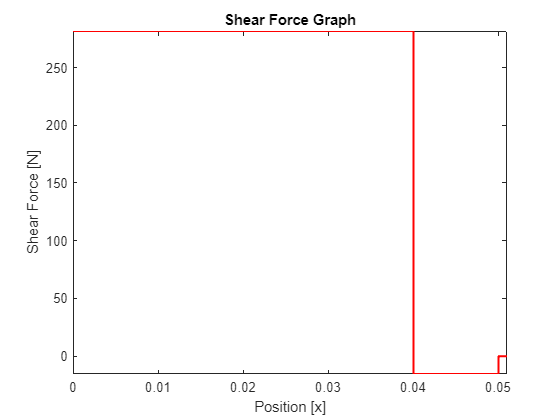

syms x
fplot((-F_A + F_B.*heaviside(x-a) - F_reaction.*heaviside(x-b)), [0, b+0.001], 'r' , 'linewidth',1.5)
title("Shear Force Graph")
xlabel('Position [x]')
ylabel('Shear Force [N]')

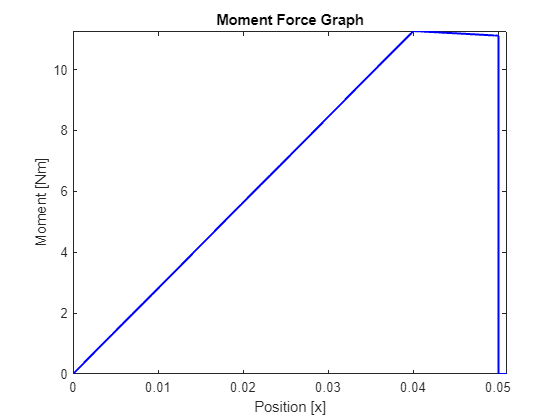

% ylim([-235,10])
% xlim([0,b+0.0005])

fplot((-F_A.*x + F_B.*heaviside(x-a).*x - F_B.*heaviside(x-a).*(a)  - F_reaction.*heaviside(x-b).*x + F_reaction.*heaviside(x-b).*(b) + M_reaction.*heaviside(x-b) ), [0, b+0.001],'b' , 'linewidth',1.5)
title("Moment Force Graph")
xlabel('Position [x]')
ylabel('Moment [Nm]')

% ylim([-3,0.5])
% xlim([0,b+0.0005])
% end
steel_1040_yield = 414;
aluminum_6082_yield = 250;
fprintf("When producing %d N of lift:\nMax stress is %.2f MPa by the notch\nResulting in a factor of saftey of %.1f for 304 stian steel",abs(lift),abs(stress)./10^6, aluminum_6082_yield./(abs(stress)./10^6))

When producing 20 N of lift:
Max stress is 235.51 MPa by the notch
Resulting in a factor of saftey of 1.1 for 304 stian steel

fprintf("The part will experience %0.3f MPa",abs(F_A/(0.8e-3*40e-3)/1e6))

The part will experience 8.800 MPa

40/abs(F_A/(0.8e-3*40e-3)/1e6)

ans = 4.5452

% plot([0:abs(max_lift)],Stress_profile)